% Read the Excel file (replace filename with yours)
data = readtable('experiment_summary.xlsx');

% Combine Method + ConvLayers into labels
labels = strcat(data.Method, ", ", string(data.ConvLayers)," layers");
unique_labels = unique(labels);

% Assign colors per unique label
colors = lines(numel(unique_labels)); % distinct colormap
color_map = containers.Map(unique_labels, num2cell(colors,2));

% Create 3D scatter plot
figure;
hold on;


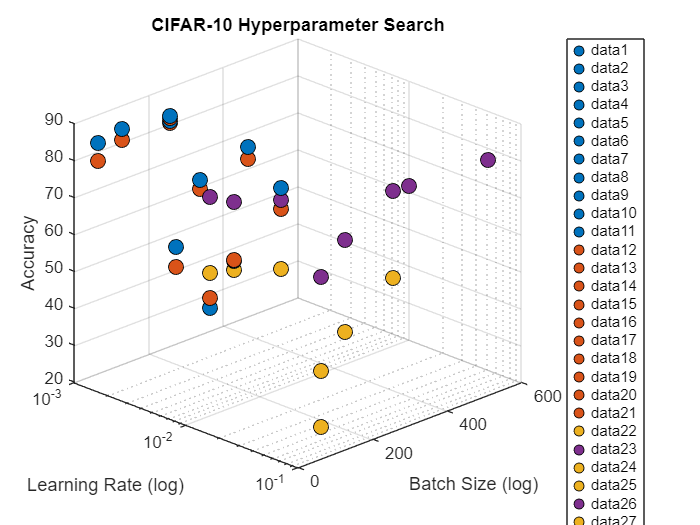

for i = 1:height(data)
    c = color_map(labels(i));
    scatter3(data.LearningRate(i), data.BatchSize(i), data.Accuracy(i), ...
             80, c, 'filled', 'MarkerEdgeColor', 'k');
end

% Set log scales for LR and Batch size
set(gca, 'XScale', 'log');
%set(gca, 'YScale', 'log');

xlabel('Learning Rate (log)');
ylabel('Batch Size (log)');
zlabel('Accuracy');
grid on;
view(45, 25);

% Legend
legend(unique_labels, 'Location', 'bestoutside');
title('CIFAR-10 Hyperparameter Search');

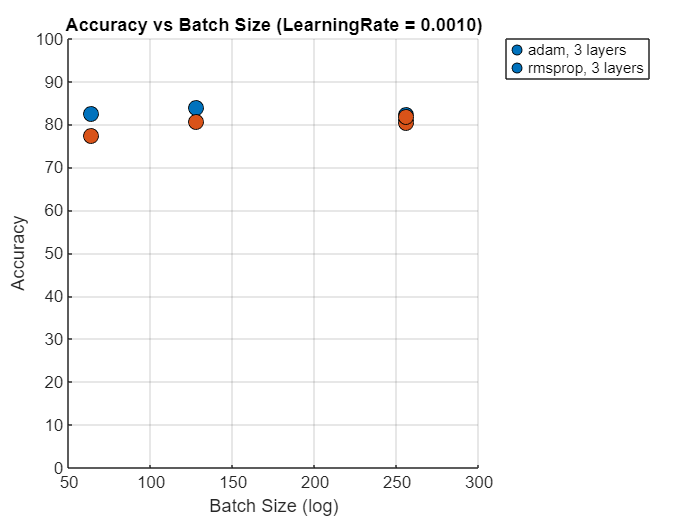

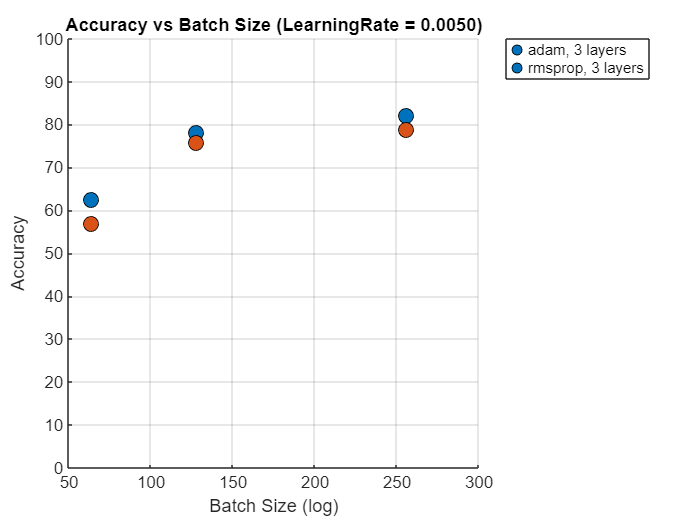

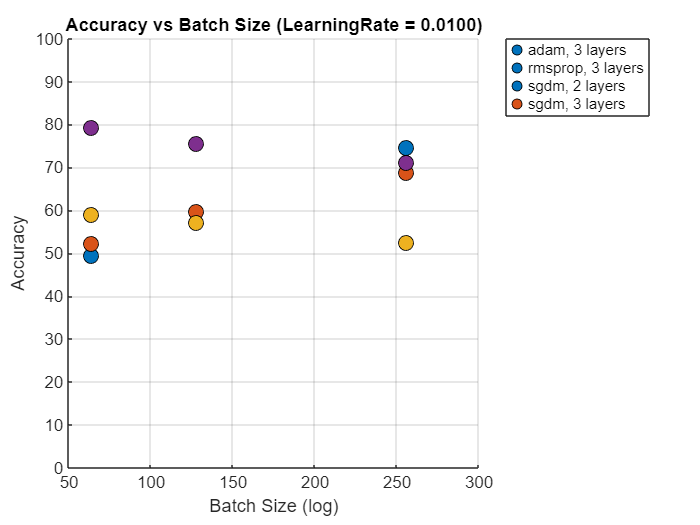

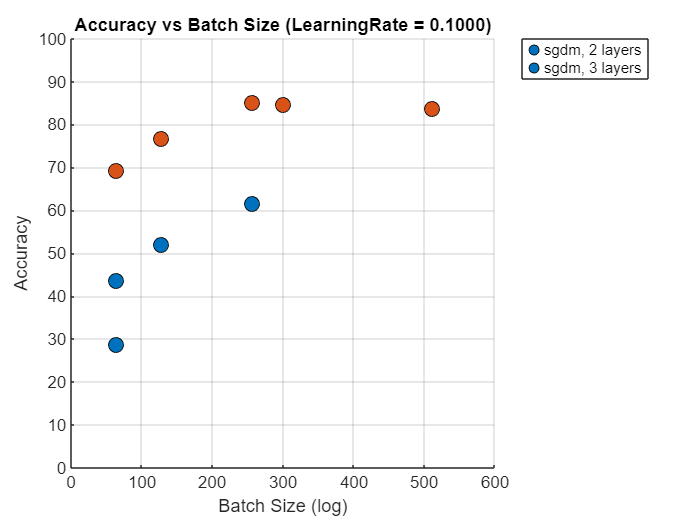


for lr_val = unique(data.LearningRate)'
    slice = data(data.LearningRate == lr_val, :);
    
    figure;
    hold on;
    
    % Unique labels for coloring
    labels_slice = strcat(slice.Method, ", ", string(slice.ConvLayers), " layers");
    unique_labels = unique(labels_slice);
    colors = lines(numel(unique_labels));
    color_map = containers.Map(unique_labels, num2cell(colors,2));
    
    for i = 1:height(slice)
        c = color_map(labels_slice(i));
        scatter(slice.BatchSize(i), slice.Accuracy(i), ...
                80, c, 'filled', 'MarkerEdgeColor', 'k');
    end
    
    %set(gca, 'XScale', 'log'); % keep BatchSize log-scaled
    xlabel('Batch Size (log)');
    ylabel('Accuracy');
    ylim([0 100]);
    legend(unique_labels, 'Location', 'bestoutside');
    title(sprintf('Accuracy vs Batch Size (LearningRate = %.4f)', lr_val));
    grid on;
end